## Work flow

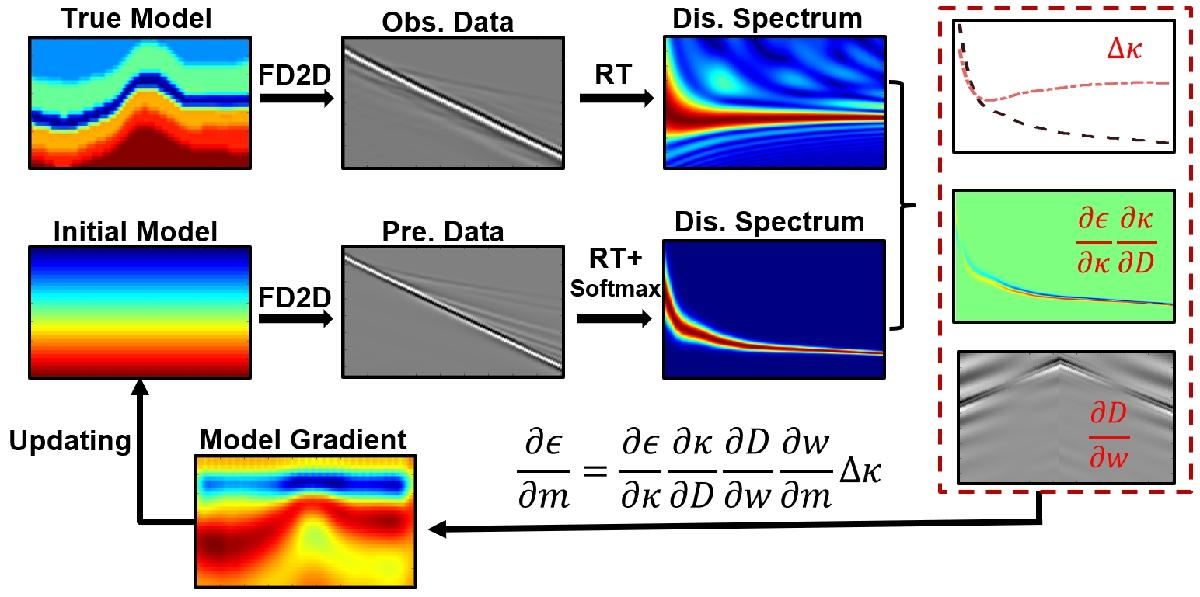

## Set up the model

clc;
clear
close all;
addpath('./core/');
load('./model/model8_2.mat');
vs_d = model8_2;
% vs_d = generateCheckerboard(34, 180, 3, 10, 500, 0.1,1); % True model
vsmin=min(vs_d(:));vsmax=max(vs_d(:));
vpmin=vsmin*1.732;vpmax=vsmax*1.732;
[nz,nx]=size(vs_d);
vs_d=single(vs_d);
vs = zeros(nz,nx); % Initial model
for i=1:nx
    vs(:,i)=linspace(vsmin,vsmax,nz);
end
vp=vs*1.732;  % vp is constant

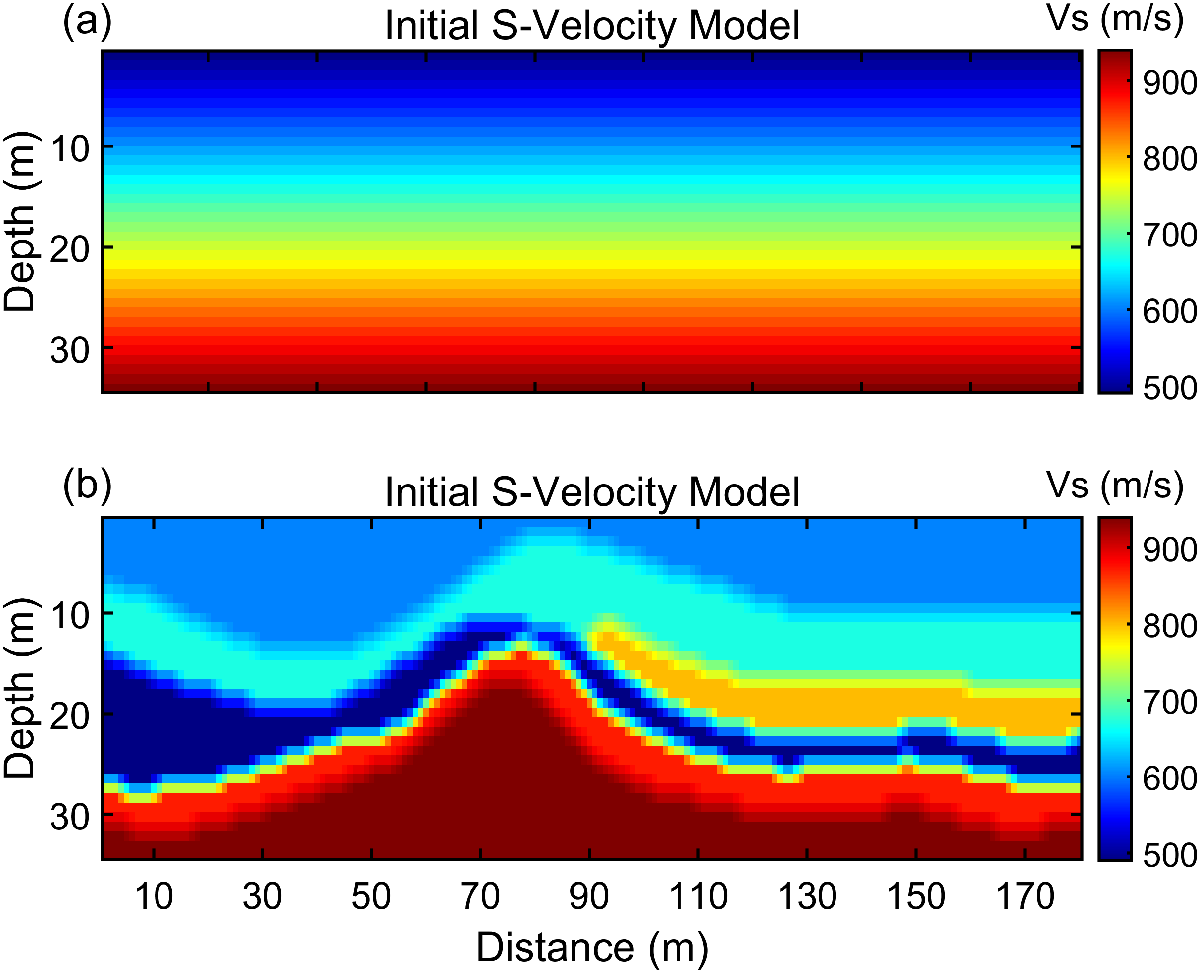

## Stability conditions, observation system


fr=30;
dx=1;%dx=(vsmin/fr/12);
dt=dx/vpmax*0.5;
dtx=dt/dx;
pickMethod=1;  %1==FDC 2==argmax
nt_wf=5;  % Storage wave field interval
nt=floor((nx*dx/vsmin/dt+1000)/10)*10-500;  % time step; Must be divisible by nt_wf
[s,nw]=ricker(fr,dt,nt); s =single(s); % source wavelet
nbc=40;   % boundary layer
% define acquisition geometry
ds=6; sx=single(1:ds:nx); sz=zeros(size(sx),'single')+1;[~,ns]=size(sx);
dg=2;gx=single(1:dg:nx);  gz=zeros(size(gx),'single')+1;  ng=numel(gx);

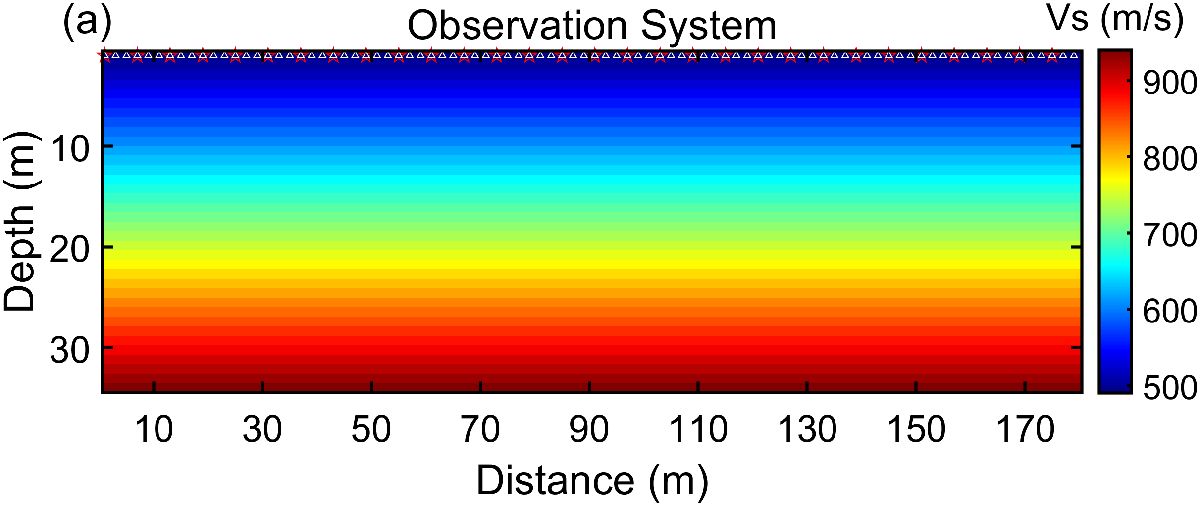

M=ds/dg;refsx=floor(sx/dg)+1;
dg=dg*dx;  % Randon Transform need real distance
% Set papramters 
pur=-0.05;   % no need to change
offset=45;   % multi-offset &the maximum offset (floor(1.2*nz*dx))
offmin=3;    % no need to change

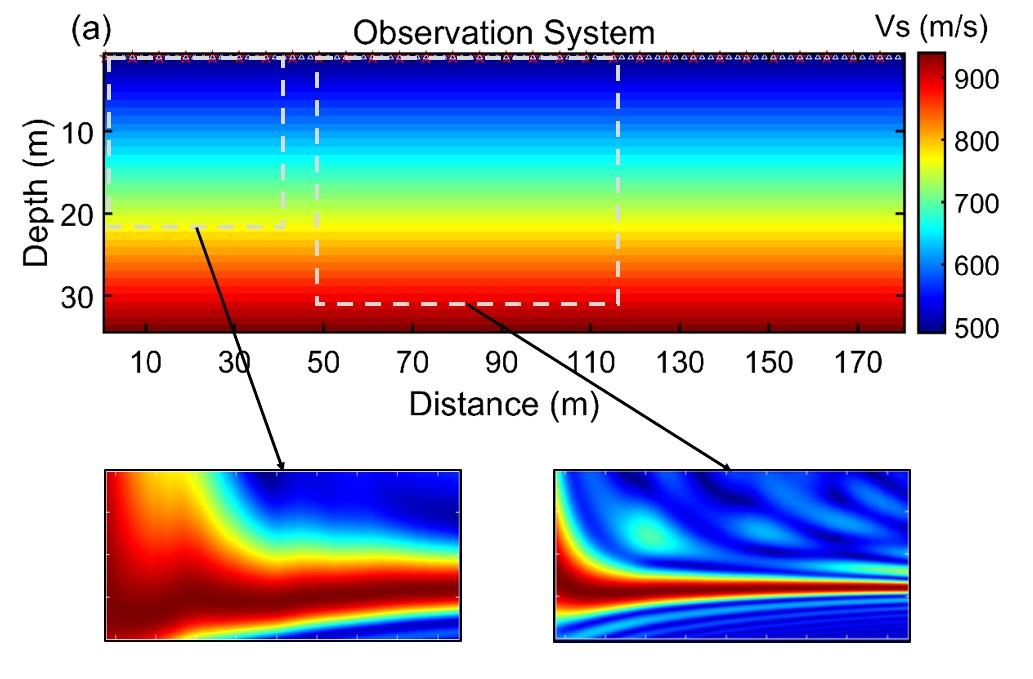

parameter_type=0;  % no need to change
fd_order=22;fsz=0;source_type='w';  % no need to change
isfs=1;  % no need to change
vmin=floor(vsmin/2);  % min phase-velocity of RT
vmax=floor(vsmax*1.2); % max phase-velocity of RT
np=vmax-vmin+1;  % no need to change
df=0.1;  % no need to change
fmin=10;  % min freq of the data
fmax=80;  % max freq of the data
ini=10;   % initial point to extract dispersion
m=0;w=3;  % no need to change
err=0.01;  % no need to change
SoftArgNorm = 1e+4;  % no need to change
iteration=190;  % no need to change
smoothZ = 1;smoothX=2;  % change if the gradient is incorrect

## Start SWD iversion

%%--------------------------------------------------------------

parallel_init(ns);  % parallel_init(ns);

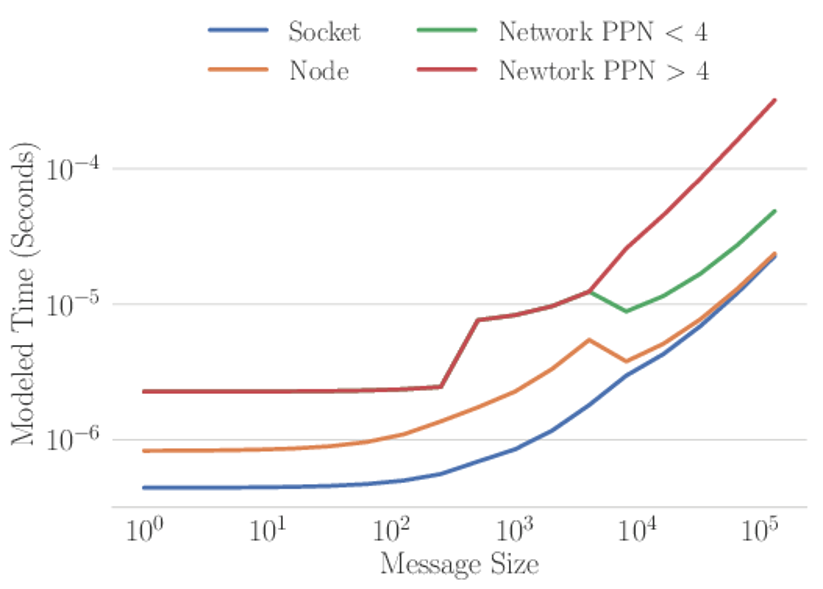

The inversion time of 60-100 parallel inversions are roughly the same.

vs_all=zeros(nz,nx,100); % Save the model of the iteration
dk_vs_all=zeros(nz,nx,100); % Save the gradient of the iteration
ind=fmin/df+1;
freq=(fmin:df:fmax);   
npair=length(freq);
win=npair+2*ind;

offsets = zeros(iteration,1);
residual = zeros(iteration,1);
space_M = zeros(np,npair);
for i =1:npair
    space_M(:,i) = linspace(1,np,np);
end

parfor is=1:ns
    [~,seismo_v_d(:,:,is)]=staggerfd_eigen(is,nbc,nt,dtx,dx,dt,sx(is),sz(is),gx,gz,s,vp,vs_d,isfs,fd_order,source_type,parameter_type,nt_wf);  
end


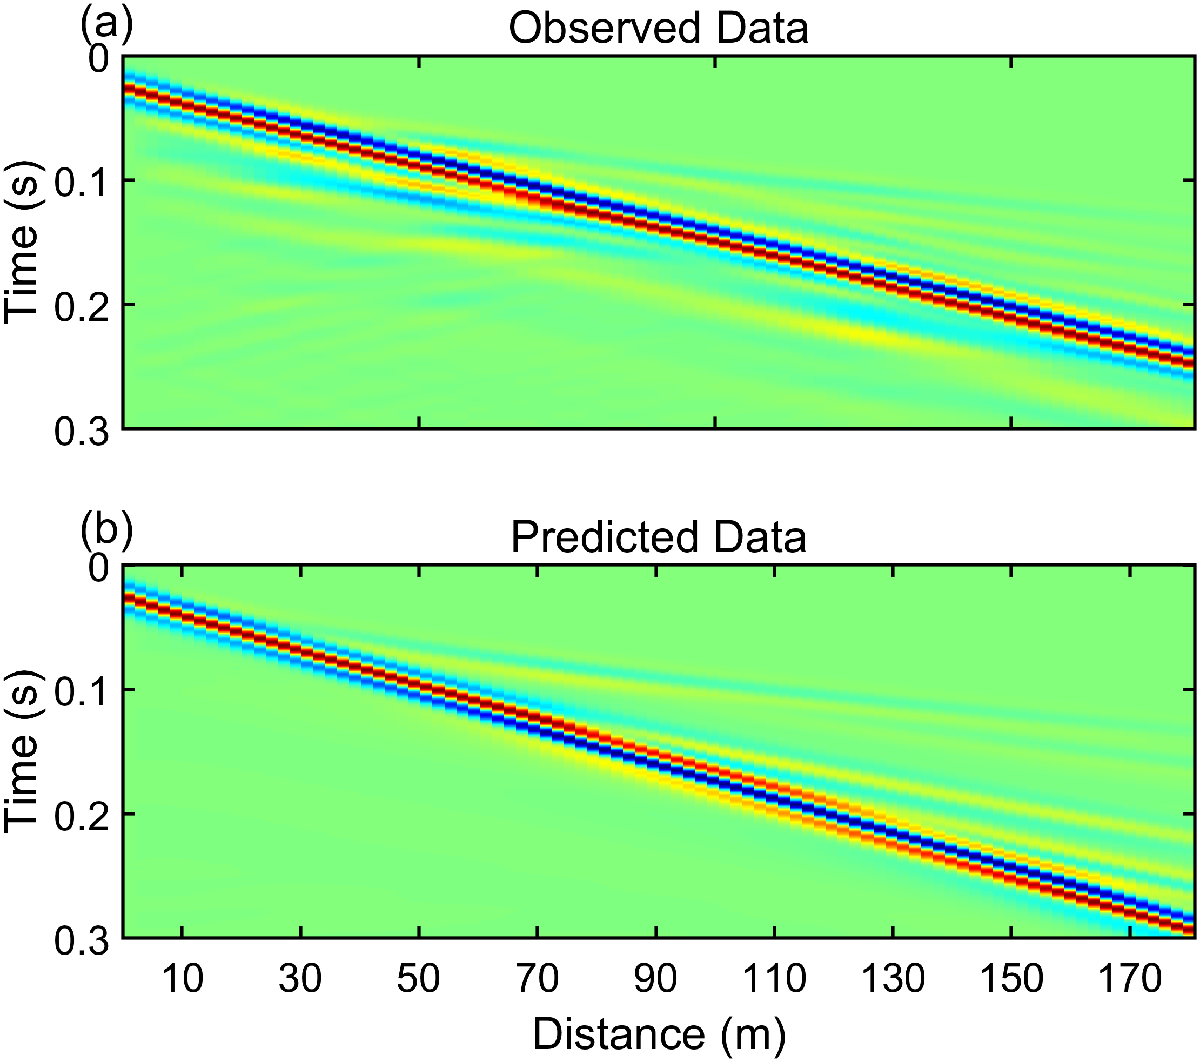

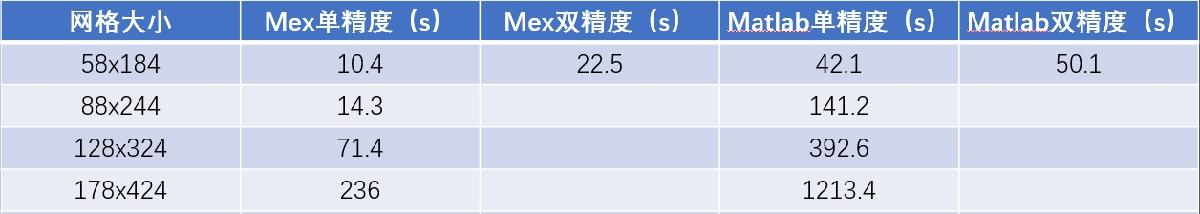

Provides single precision and double precision modes, but single precision will result in different gradient smoothing results. (MTIMES (*) does not support one sparse argument and one single precision argument.)


[a,b]=size(seismo_v_d(:,:,1));  

k =1;

while (k<=iteration)  
tic;
display(['Elastic_LSM, k=',num2str(k),' iteration=',num2str(iteration)]);

ml = zeros(np,npair,ns);
ml1 = zeros(np,npair,ns);

cr_0 = 1.*ones(npair,ns);
cr_0l = 1.*ones(npair,ns);

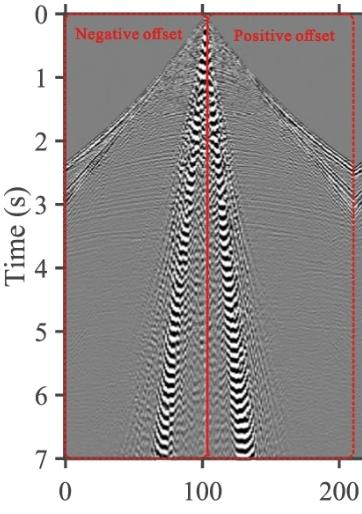

parfor is=1:ns-floor(m/M)-round(w/M)
    [ml(:,:,is),dataLen]=RTr(seismo_v_d(:,:,is),is,df,dt,np,vmin,vmax,fmin,fmax,a,b,dg,offset,m,M);
    [~,cr_0(:,is)] = LHDispPick(ml(:,:,is),vmin,cr_0(:,is),pickMethod,ini);
end
parfor is=round(w/M)+floor(m/M)+1:ns
    [ml1(:,:,is),dataLen]=RTl(seismo_v_d(:,:,is),is,df,dt,np,vmin,vmax,fmin,fmax,a,b,dg,offset,m,M);
    [~,cr_0l(:,is)] = LHDispPick(ml1(:,:,is),vmin,cr_0l(:,is),pickMethod,ini);
end



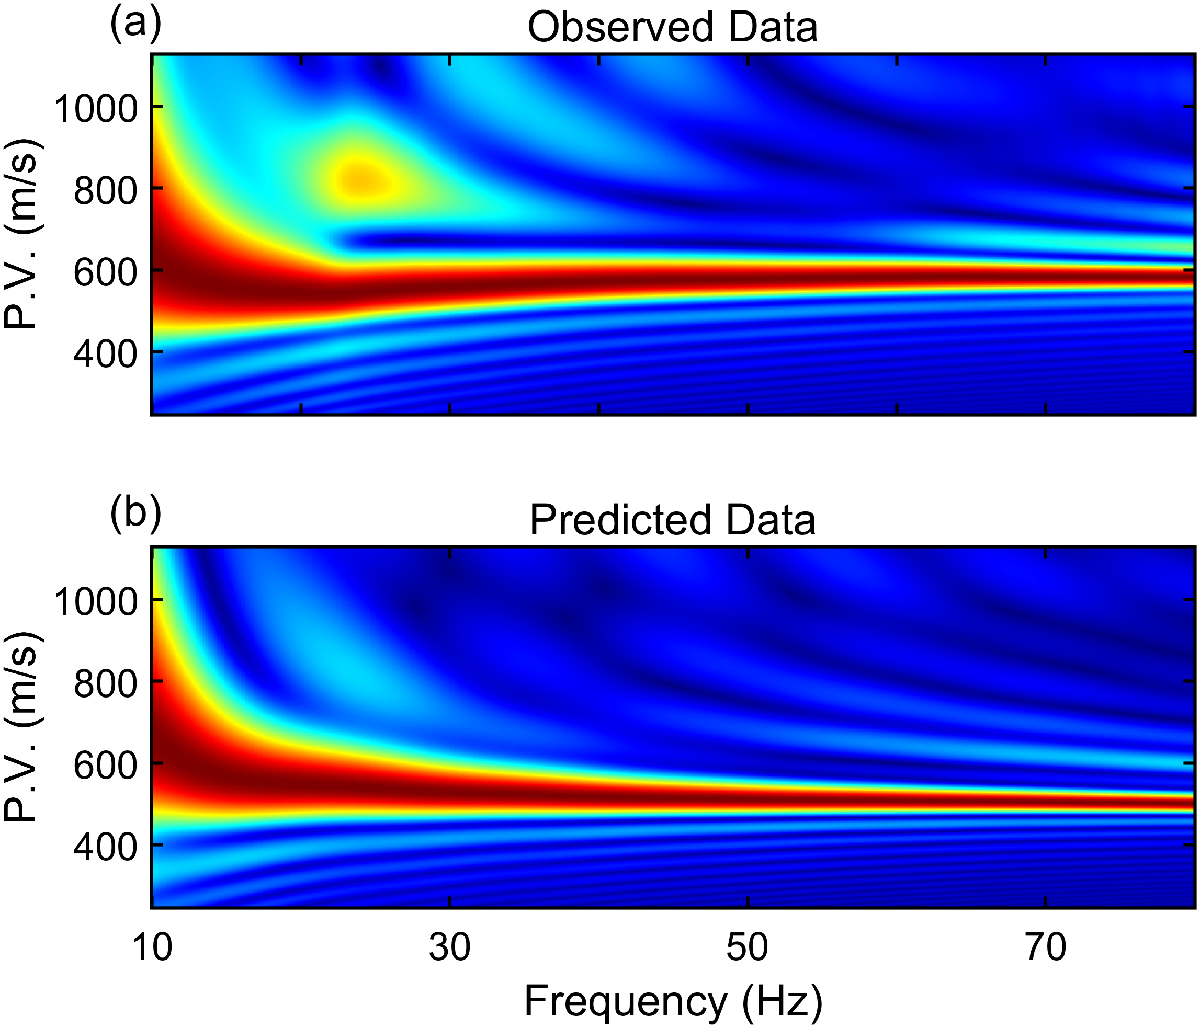

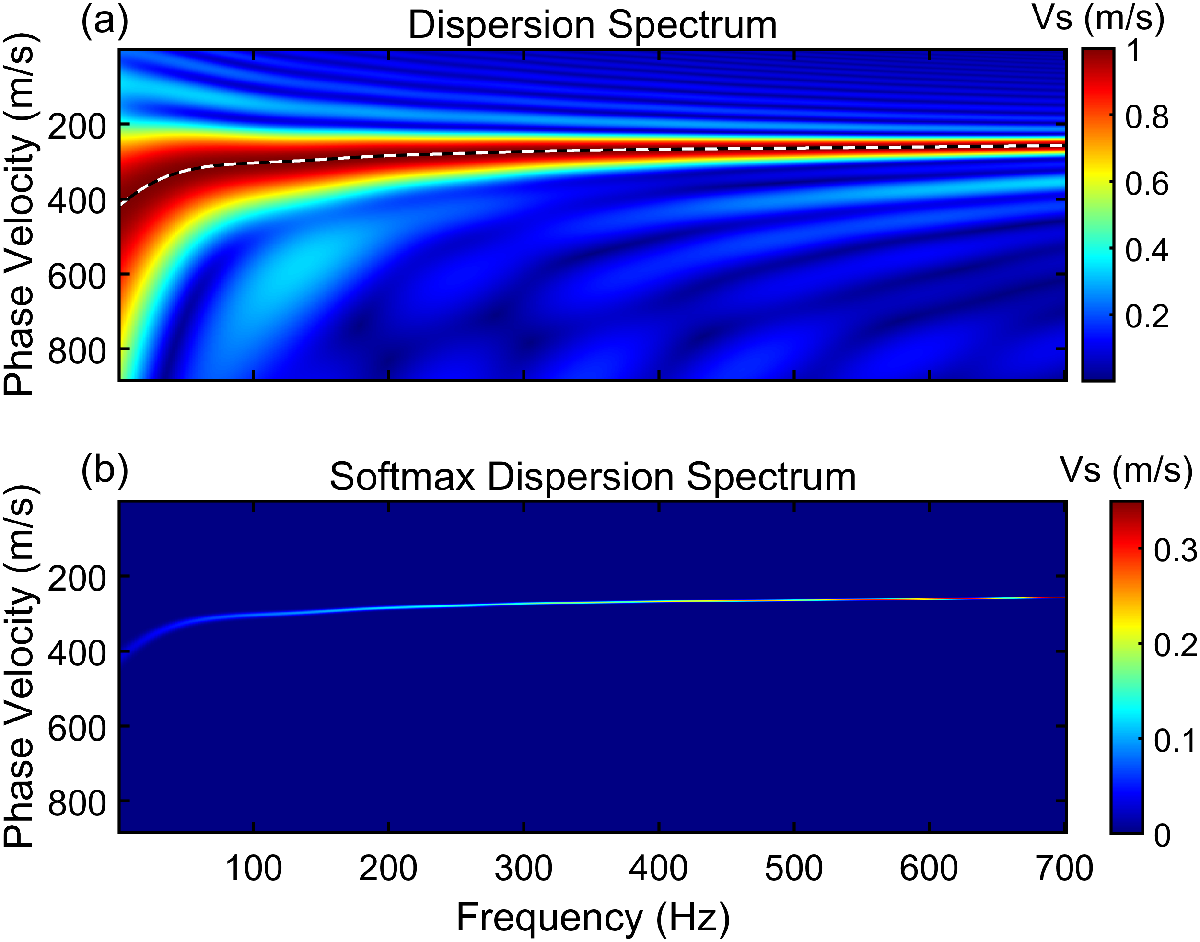


cr_pre_r = 1.*ones(npair,ns);
cr_pre_l = 1.*ones(npair,ns);
g_cl=zeros(nz,nx);
g_cm=zeros(nz,nx);
g_illum=zeros(nz,nx);

parfor is=1:ns
    [~,seismo_v,wavefield_gradient]=staggerfd_eigen(is,nbc,nt,dtx,dx,dt,sx(is),sz(is),gx,gz,s,vp,vs,isfs,fd_order,source_type,parameter_type,nt_wf);
    saveForBackwardr = 0;
    saveForBackwardl = 0;
    if is<=ns-floor(m/M)-round(w/M)
        [mlr,dataLen,saveForBackwardr]=RTrAD(seismo_v,is,df,dt,np,vmin,vmax,fmin,fmax,a,b,dg,offset,m,M); % Cal. the predicetd data dispersion curve for two sides 
        [res_r(is),cr_pre_r(:,is)] = LHDispPick(mlr,vmin,cr_0(:,is),pickMethod,ini);
        saveForBackwardr.cr_r = cr_pre_r(:,is)-vmin;
    end
    
    if is>=round(w/M)+floor(m/M)+1
        [mll,dataLen,saveForBackwardl]=RTlAD(seismo_v,is,df,dt,np,vmin,vmax,fmin,fmax,a,b,dg,offset,m,M); % Cal. the predicetd data dispersion curve for two sides 
        [res_l(is),cr_pre_l(:,is)] = LHDispPick(mll,vmin,cr_0l(:,is),pickMethod,ini);
        saveForBackwardl.cr_l = cr_pre_l(:,is)-vmin;
    end
    grad_outputr = cr_pre_r(:,is)-cr_0(:,is);
    grad_outputl = cr_pre_l(:,is)-cr_0l(:,is);
        % [seismo_v_d1]=weight_data_muti3(seismo_v_d(:,:,is),seismo_v,is,dt,df,offset,dg,0,w,M,m,ns,refsx,win,fmin,fmax, ...
        % cr_0(:,is),cr_0l(:,is),cr_pre_r(:,is),cr_pre_l(:,is),ind);% Uncomment there two lines to enable the WD method
    [seismo_v_d1]=ADWDgrad_1(nt,ng,ns,npair,is,w,m,M,SoftArgNorm,grad_outputr,grad_outputl,space_M,saveForBackwardr,saveForBackwardl);% Uncomment this line to enable the SWD method
    % [seismo_v_d1,res_r]=FWIresidual(seismo_v,seismo_v_d(:,:,is));
    [cl_img,cm_img,illum_div]=e2drtm_eigen(wavefield_gradient,single(seismo_v_d1),is,nbc,nt,dtx,dx,dt,gx,gz,s,vp,vs,isfs,fd_order,parameter_type,nt_wf);
    g_cl = g_cl+cl_img;g_cm = g_cm+cm_img;g_illum = g_illum+illum_div;
end

residual(k)=mean(mean(res_r));%+mean(mean(res_l));
display(['residual = ',num2str( residual(k) ),' k=',num2str(k)]);
res0=residual(k); 
g_cl=g_cl./g_illum;g_cm=g_cm./g_illum;
dk_vs = -4*vs.*g_cl+2*vs.*g_cm;
dk_vs=single(smooth2a(double(dk_vs),smoothZ,smoothX));  % Smooth the Vs gradient

if k==1
    f1=0.5;
end
v_mean=(sum(vs(:).*vs(:)))^0.5;
g_mean=(sum(dk_vs(:).*dk_vs(:)))^0.5;
alpha=v_mean/g_mean*pur;  
display(['v_mean=',num2str(v_mean),' g_mean=',num2str(g_mean),' alpha=',num2str(alpha)]);
vs1=vs+alpha*f1*dk_vs;
vs1(vs1<vsmin)=vsmin;vs1(vs1>vsmax)=vsmax;


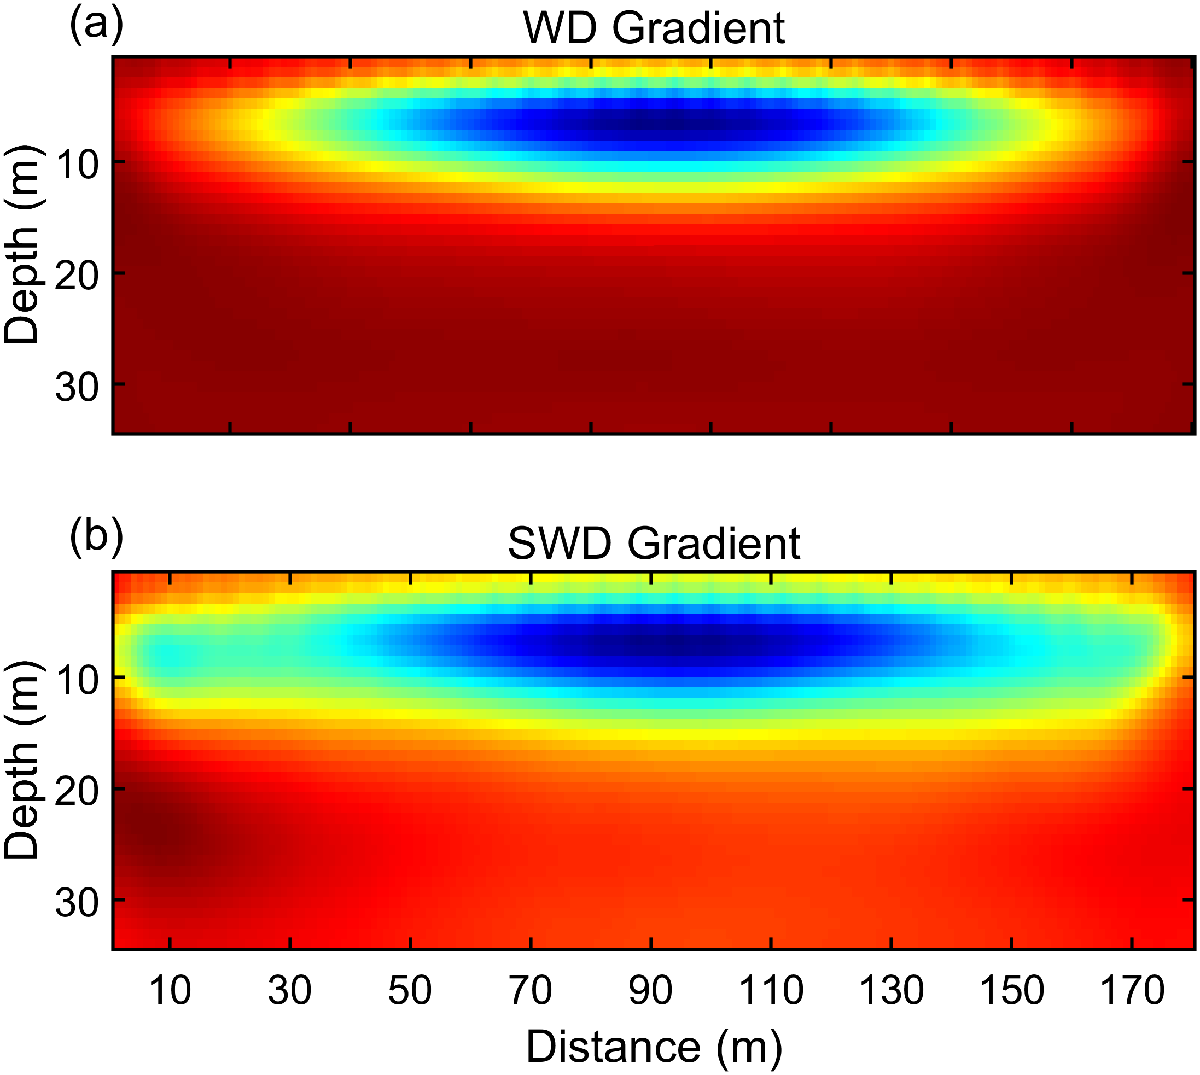

parfor is=1:ns
    [~,seismo_v,~]=staggerfd_eigen(is,nbc,nt,dtx,dx,dt,sx(is),sz(is),gx,gz,s,vp,vs1,isfs,fd_order,source_type,parameter_type,nt_wf);
    if is<=ns-floor(m/M)-round(w/M)
        [mlr,dataLen]=RTr(seismo_v,is,df,dt,np,vmin,vmax,fmin,fmax,a,b,dg,offset,m,M); % Cal. the predicetd data dispersion curve for two sides 
        [res_r(is),cr_pre_r(:,is)] = LHDispPick(mlr,vmin,cr_0(:,is),pickMethod,ini);
    
    end
    if is>=round(w/M)+floor(m/M)+1
        [mll,dataLen]=RTl(seismo_v,is,df,dt,np,vmin,vmax,fmin,fmax,a,b,dg,offset,m,M);
        [res_l(is),cr_pre_l(:,is)] = LHDispPick(mll,vmin,cr_0l(:,is),pickMethod,ini);
    end


end
res1=mean(mean(res_r));%+mean(mean(res_l));
display(['f1= ',num2str(f1),' res1= ',num2str(res1)]);

if res1>res0
    while res1>res0 && f1>0.0001
        f2=f1; res2=res1;
        f1=f1*0.5;
        vs1=vs+alpha*f1*dk_vs;
        vs1(vs1<vsmin)=vsmin;vs1(vs1>vsmax)=vsmax; 
        %vs1(vp./vs1<1.3)=vp(vp./vs1<1.3)/1.3;
        
        
        parfor is=1:ns
            [~,seismo_v,~]=staggerfd_eigen(is,nbc,nt,dtx,dx,dt,sx(is),sz(is),gx,gz,s,vp,vs1,isfs,fd_order,source_type,parameter_type,nt_wf);
            if is<=ns-floor(m/M)-round(w/M)
                [mlr,dataLen]=RTr(seismo_v,is,df,dt,np,vmin,vmax,fmin,fmax,a,b,dg,offset,m,M); % Cal. the predicetd data dispersion curve for two sides 
                [res_r(is),cr_pre_r(:,is)] = LHDispPick(mlr,vmin,cr_0(:,is),pickMethod,ini);
            
            end
            if is>=round(w/M)+floor(m/M)+1
                [mll,dataLen]=RTl(seismo_v,is,df,dt,np,vmin,vmax,fmin,fmax,a,b,dg,offset,m,M);
                [res_l(is),cr_pre_l(:,is)] = LHDispPick(mll,vmin,cr_0l(:,is),pickMethod,ini);
            end
        
        end
        res1=mean(mean(res_r));%+mean(mean(res_l));
        display(['f1= ',num2str(f1),' res1= ',num2str(res1)]);
    end
else
    f2=f1*2;
    vs1=vs+alpha*f2*dk_vs; 
    vs1(vs1<vsmin)=vsmin;vs1(vs1>vsmax)=vsmax;

    parfor is=1:ns
        [~,seismo_v,~]=staggerfd_eigen(is,nbc,nt,dtx,dx,dt,sx(is),sz(is),gx,gz,s,vp,vs1,isfs,fd_order,source_type,parameter_type,nt_wf);
        if is<=ns-floor(m/M)-round(w/M)
            [mlr,dataLen]=RTr(seismo_v,is,df,dt,np,vmin,vmax,fmin,fmax,a,b,dg,offset,m,M); % Cal. the predicetd data dispersion curve for two sides 
            [res_r(is),cr_pre_r(:,is)] = LHDispPick(mlr,vmin,cr_0(:,is),pickMethod,ini);
        
        end
        if is>=round(w/M)+floor(m/M)+1
            [mll,dataLen]=RTl(seismo_v,is,df,dt,np,vmin,vmax,fmin,fmax,a,b,dg,offset,m,M);
            [res_l(is),cr_pre_l(:,is)] = LHDispPick(mll,vmin,cr_0l(:,is),pickMethod,ini);
        end
    
    end
    res2=mean(mean(res_r));%+mean(mean(res_l));
    display(['f2= ',num2str(f2),' res2= ',num2str(res2)]);

end
gama=(f1^2*(res0-res2)+f2^2*(res1-res0))/(2*res0*(f1-f2)+2*res1*f2-2*res2*f1);

if isinf(gama)
    gama=0;
end
display(['gama= ',num2str(gama),' numerical step_length= ',num2str(gama*alpha)]);
vs1=vs+alpha*gama*dk_vs;
vs1(vs1<vsmin)=vsmin;vs1(vs1>vsmax)=vsmax;

parfor is=1:ns
    [~,seismo_v,~]=staggerfd_eigen(is,nbc,nt,dtx,dx,dt,sx(is),sz(is),gx,gz,s,vp,vs1,isfs,fd_order,source_type,parameter_type,nt_wf);
    if is<=ns-floor(m/M)-round(w/M)
        [mlr,dataLen]=RTr(seismo_v,is,df,dt,np,vmin,vmax,fmin,fmax,a,b,dg,offset,m,M); % Cal. the predicetd data dispersion curve for two sides 
        [res_r(is),cr_pre_r(:,is)] = LHDispPick(mlr,vmin,cr_0(:,is),pickMethod,ini);
    
    end
    if is>=round(w/M)+floor(m/M)+1
        [mll,dataLen]=RTl(seismo_v,is,df,dt,np,vmin,vmax,fmin,fmax,a,b,dg,offset,m,M);
        [res_l(is),cr_pre_l(:,is)] = LHDispPick(mll,vmin,cr_0l(:,is),pickMethod,ini);
    end

end

res3=mean(mean(res_r));%+mean(mean(res_l));
display(['res3= ',num2str(res3)]);
if (res3>res1 || res3>res2)
    if res1>res2
        res0=res2;
        gama=f2; 
    else
        res0=res1;
        gama=f1; 
    end
    vs1=vs+alpha*gama*dk_vs;      
    vs1(vs1<vsmin)=vsmin;vs1(vs1>vsmax)=vsmax; 

else
    res0=res3;
end
vs=vs1;
vs_all(:,:,k) = vs1; 
dk_vs_all(:,:,k) = dk_vs; 
offsets(k) = offset;

if (k>1) && ((residual(k) - res0)/residual(k)) < err
    offset = offset - 3  
    f1=0.5;
end
k = k +1;

if offset==3 
    break
end


end

toc; 

dfs = mean(mean((vs-vs_d).^2))